# EVM Measurement

This example walks through evaluating the error vector magnitude (EVM) for a waveform generated by the 5G waveform generator app. The example also shows the effect of adding impairments within the app on the evaluated EVM.

- **Adding Impairments.**

- **Observe the introduced phase noise and nonlinearity models.**

- **Calculate the EVM****.**

- **Observe both waveforms on the Spectrum Analyzer**

### **1. Adding Impairments**

 ***Click ***on NR Test Models and create the waveform from Exercise 1 which had the following properties:

- Test Model: NR-FR1-TM3.1

- SubCarrier Spacing: 30 kHz

- Channel Bandwidth: 100 MHz

- Duplex Mode: FDD

***Click*** on Impairments 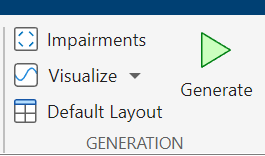 and add the following:

- Phase noise with parameters: 

              Levels=[-95 -115] dBc/Hz

              Frequency offsets=[1e4 1e5] Hz.

- IQ imbalance: 

             Amplitude imbalance= 0.2 dB 

             Phase imbalance= 0.5 rad.

- Memoryless cubic nonlinearity: 

             Linear gain= 1dB

             IIP3=19 dBm 

             AM/PM conversion= 10 deg/dB.

***Click*** on Generate  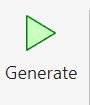 

***Click*** on Export  drop down menu to export the MATLAB script.

***Observe*** that the impairments are added at the end of the script.

***Save*** the generated file then ***run*** it.

### **2. Observe the introduced phase noise and memoryless cubic nonlinearity models.**

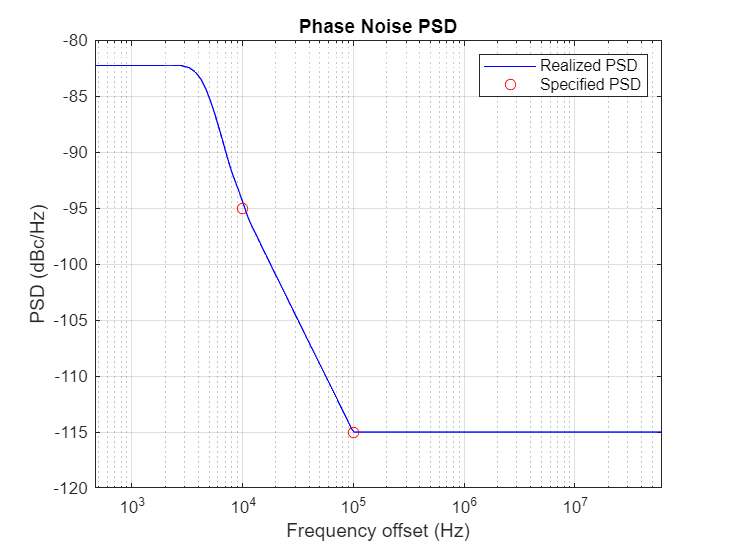

p = addpath(genpath(pwd));
load Unimpaired_waveform.mat
%%%%%%%%%%%%%%%%%% CODE TO ADD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Observe the phase noise model by using the command visualize() to view the object phaseNoise.
% Hint: Type doc comm/visualize in the command window.
visualize(phaseNoise);

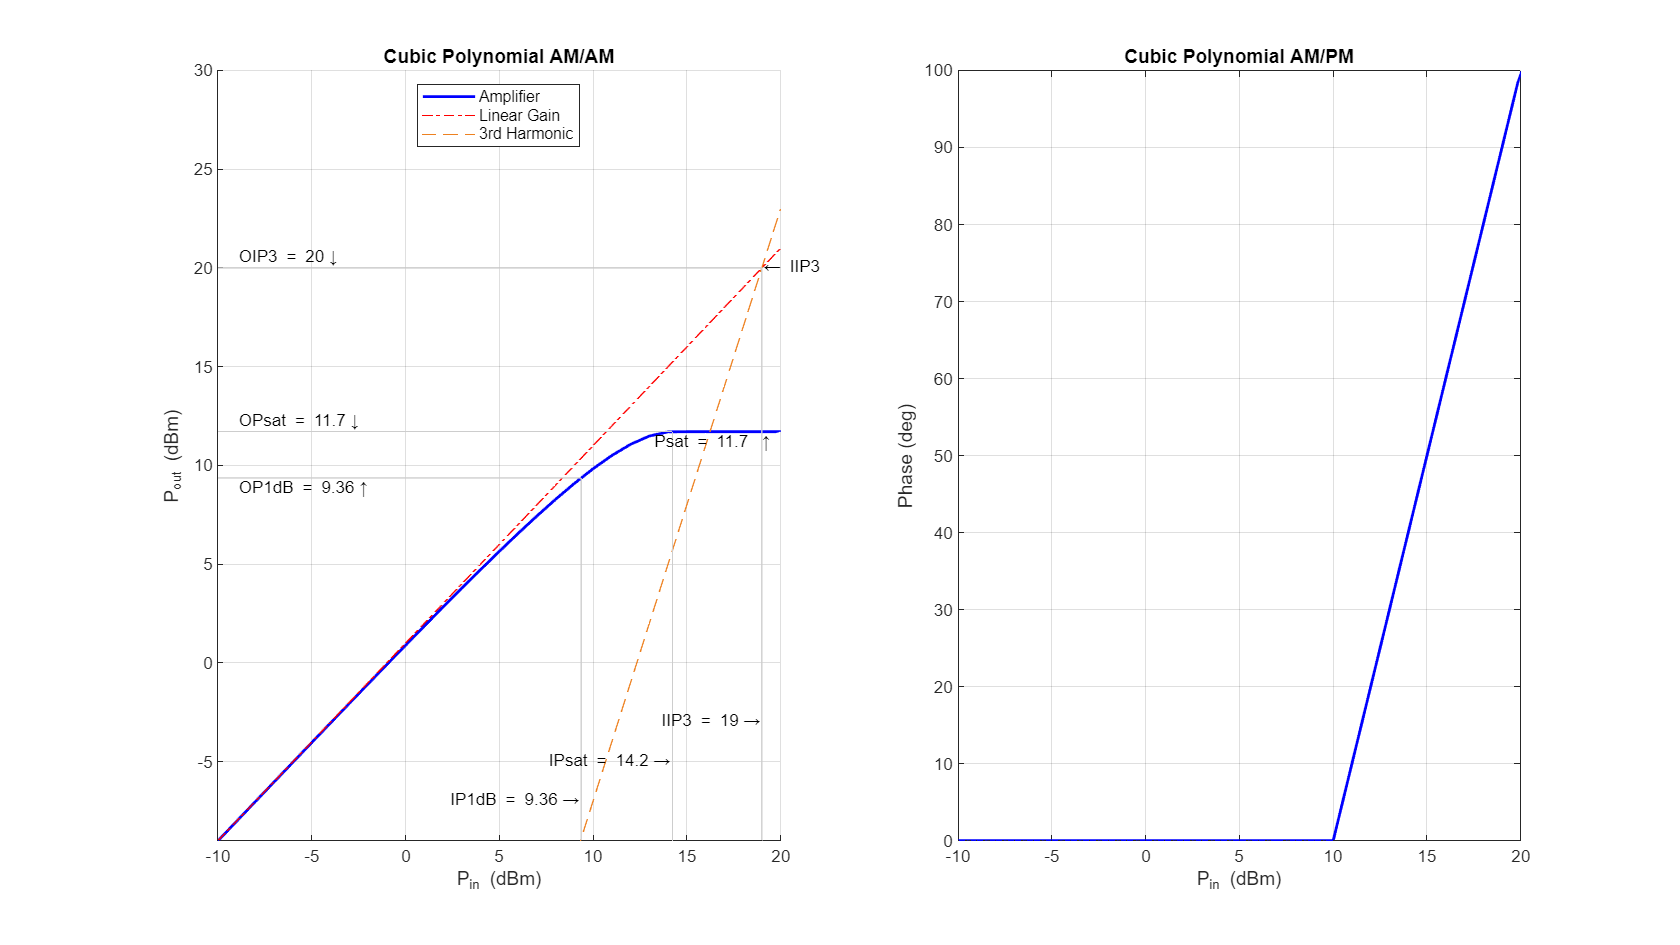

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%% CODE TO ADD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To observe the memoryless cubic nonlinearity (Power Amplifier) model, call plot(nonlin)
plot(nonlin)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 


### **3. Calculate the EVM**

- For the Unimpaired waveform:

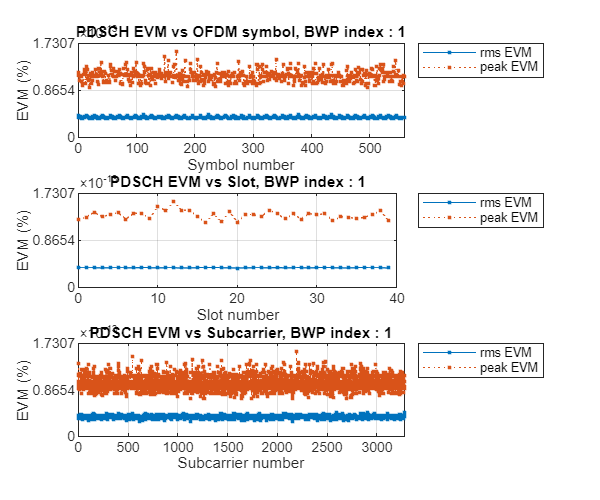

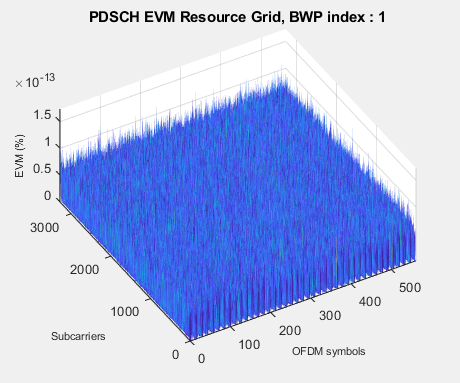

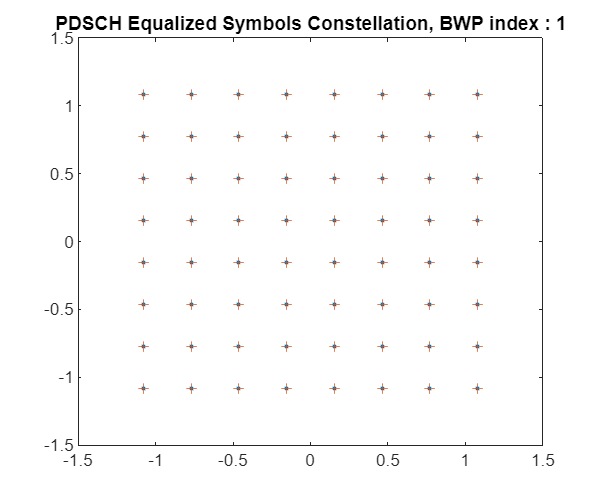

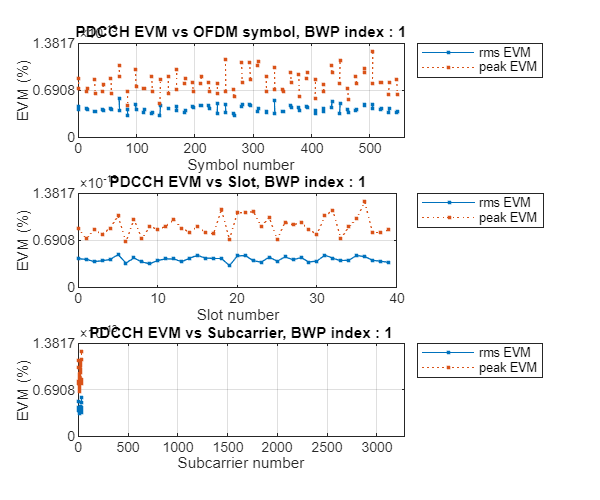

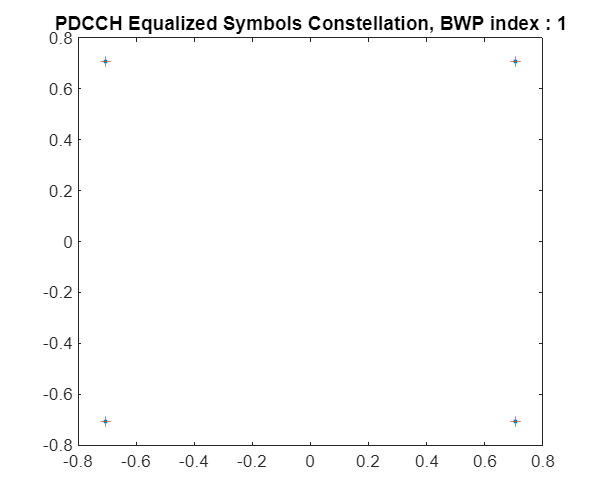

evm3GPP=false;      %To measure EVM as defined in TS 38.104, Annex B(FR1) / Annex C(FR2), set evm3GPP to true. 
                    % evm3GPP is disabled by default. evm3GPP is disabled for PDCCH EVM measurement.
targetRNTIs=[];     %To override the default PDSCH RNTIs, specify the targetRNTIs vector
plotEVM=true;       %To plot EVM statistics, set plotEVM to true. To disable the plots, set plotEVM to false
displayEVM=false;   %To print EVM statistics, set displayEVM to true. To disable the prints, set displayEVM to false.
IQImbalanceON=false;

cfg = struct();
cfg.Evm3GPP = evm3GPP;
cfg.TargetRNTIs = [];
cfg.PlotEVM = plotEVM;
cfg.DisplayEVM = displayEVM;
cfg.IQImbalance = IQImbalanceON;

%%%%%%%%%%%%%%%%%% CODE TO ADD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compute and display EVM measurements for the unimpaired waveform using the helper function below
%   [evmInfo,EQSYM,REFSYM] = hNRDownlinkEVM(WAVECONFIG,RXWAVEFORM,CFG);
%                         WAVECONFIG         - Input object of type 'nrDLCarrierConfig'
%
%                         RXWAVEFORM         - Time domain baseband IQ samples input. Timing of
%                                              the waveform is assumed to be slot-wise aligned
%                                              with sample level fine-tuning performed
%                                              subsequently. The length of the waveform can be an
%                                              arbitrary number of slots
%                         CFG                - Input structure with the fields required
%                                              for EVM calculation
% Hint: WAVECONFIG= cfgDLTM and CFG=cfg. Use the Unimpaired_waveform.
[evmInfo,~,~] = hNRDownlinkEVM(cfgDLTM,Unimpaired_waveform,cfg);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 


disp([' Averaged overall PDSCH RMS EVM Unimpaired: ' num2str(evmInfo.PDSCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDSCH RMS EVM Unimpaired: 0.000 %


disp([' Averaged overall PDCCH RMS EVM Unimpaired: ' num2str(evmInfo.PDCCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDCCH RMS EVM Unimpaired: 0.000 %


  2. For the impaired waveform:

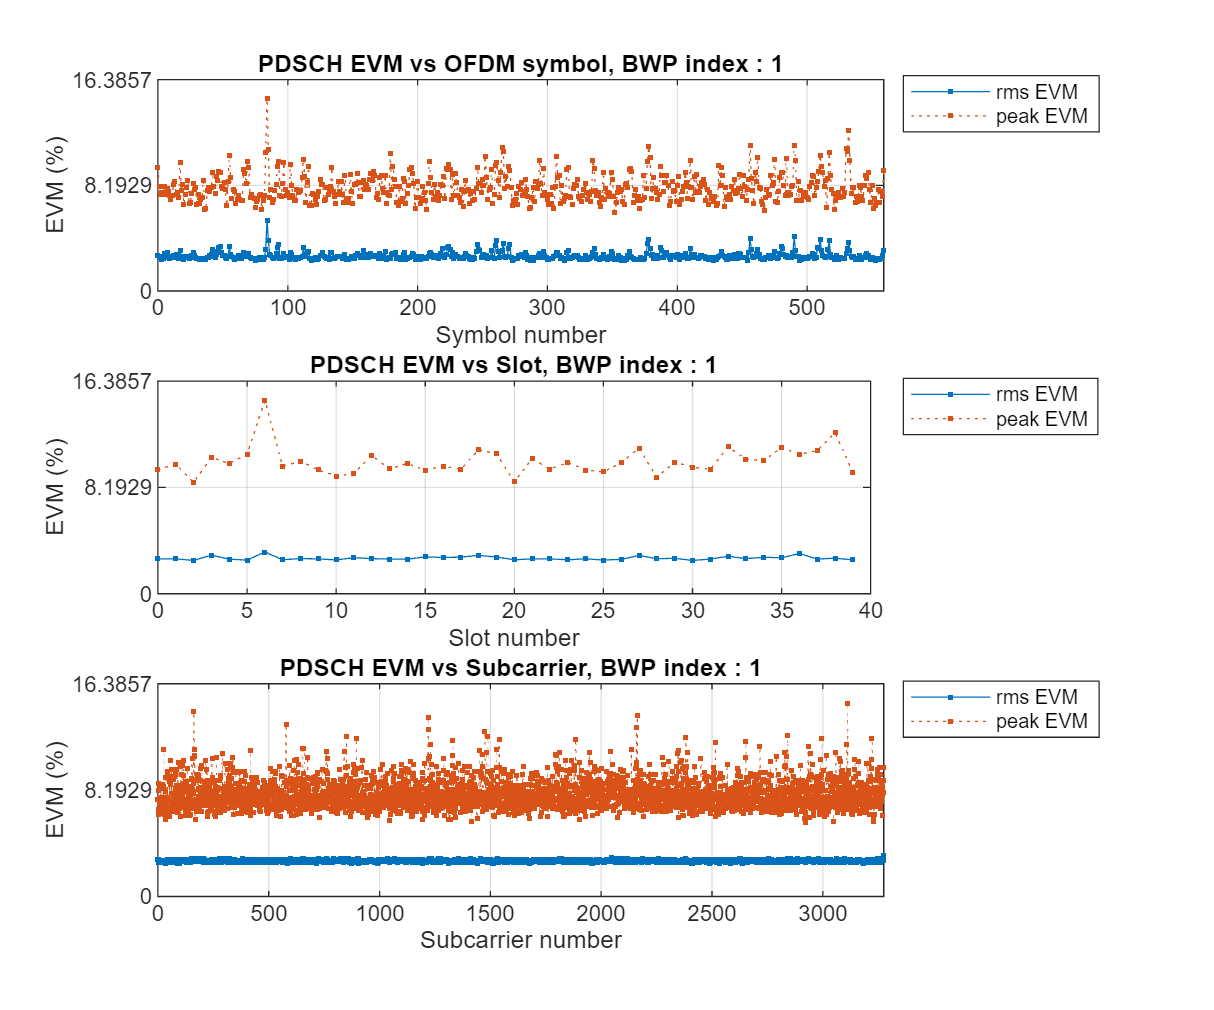

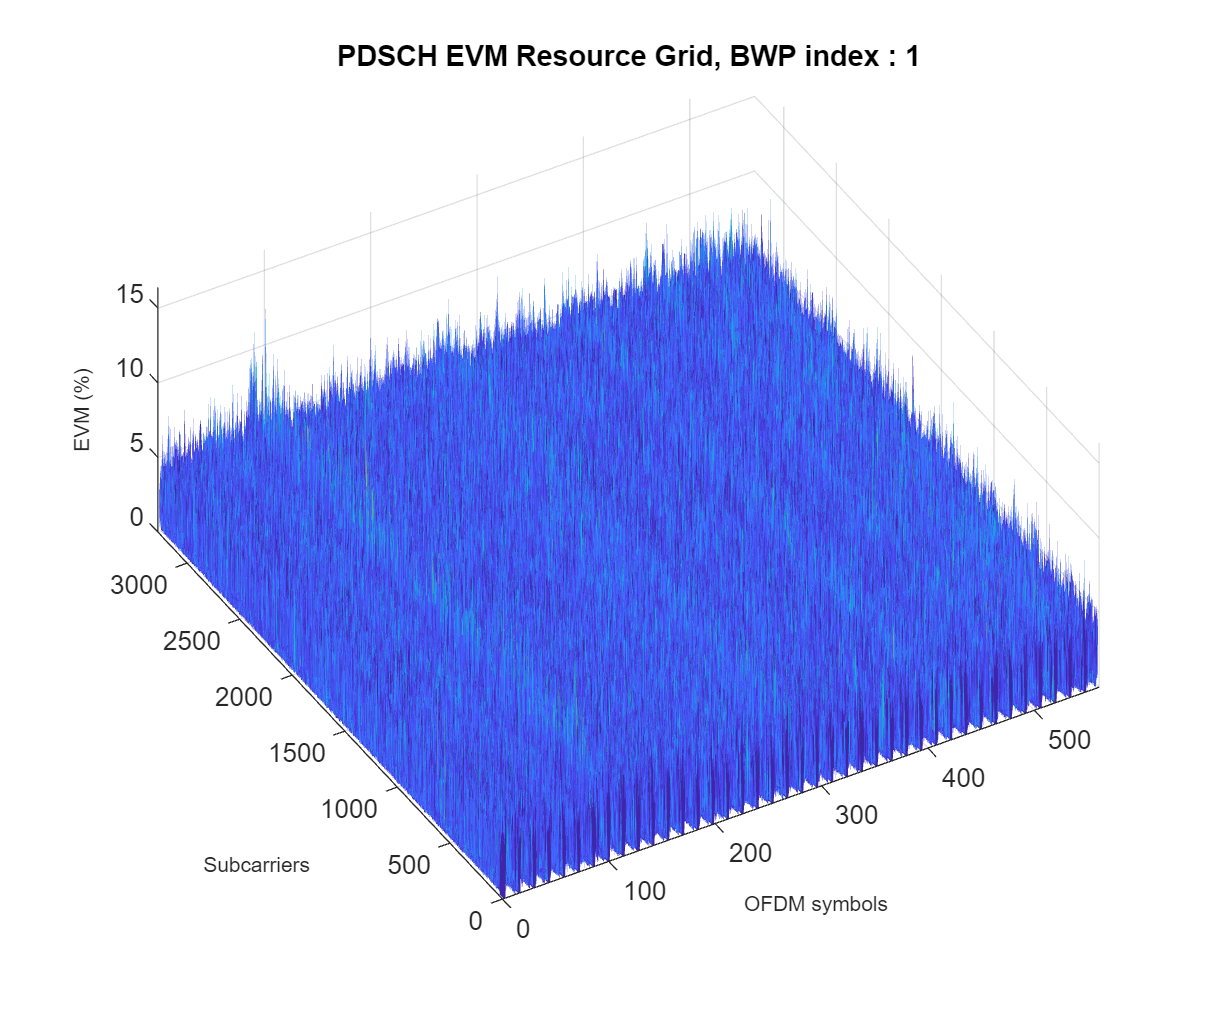

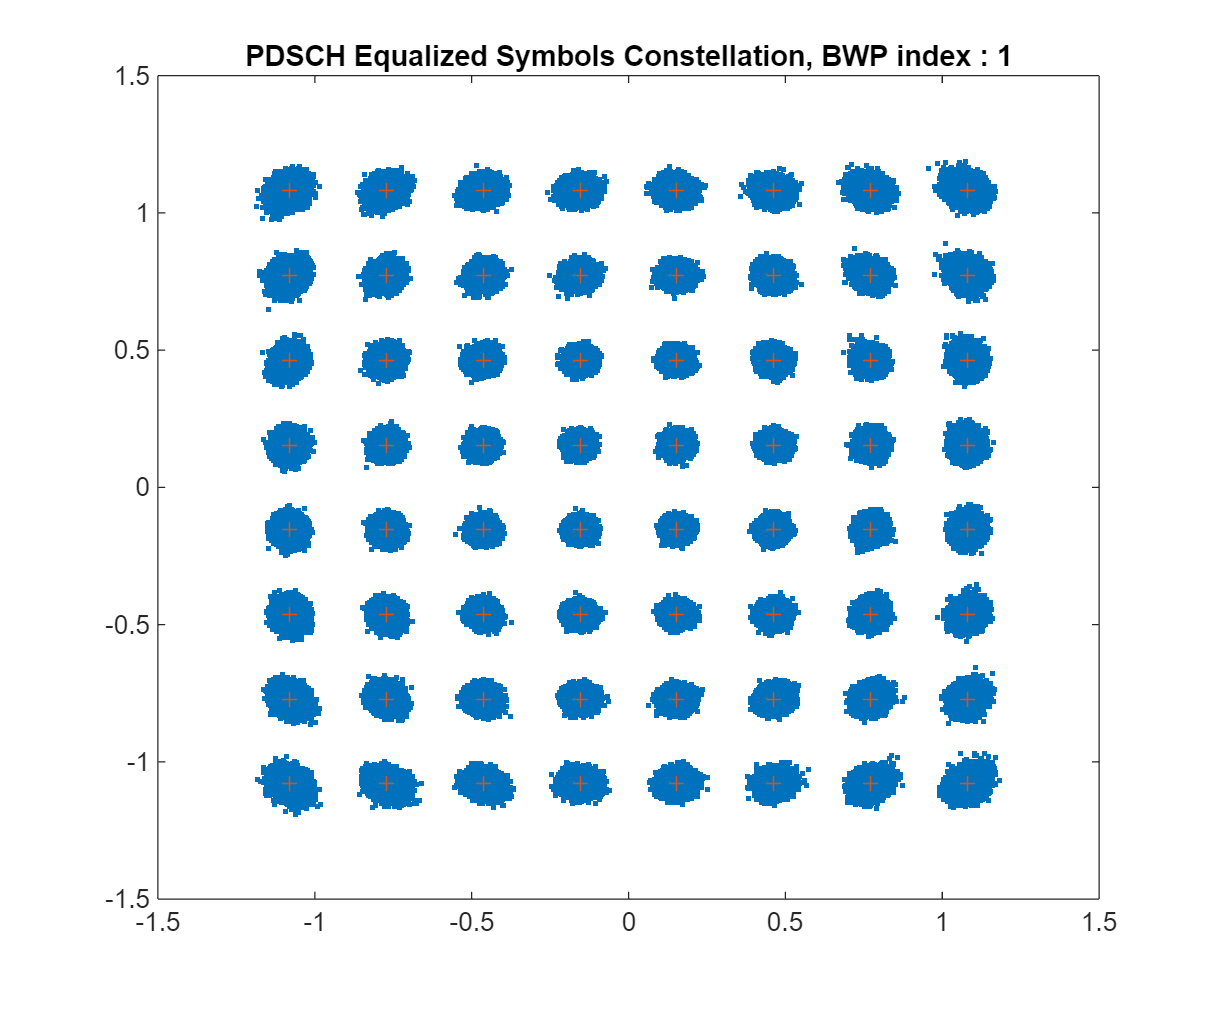

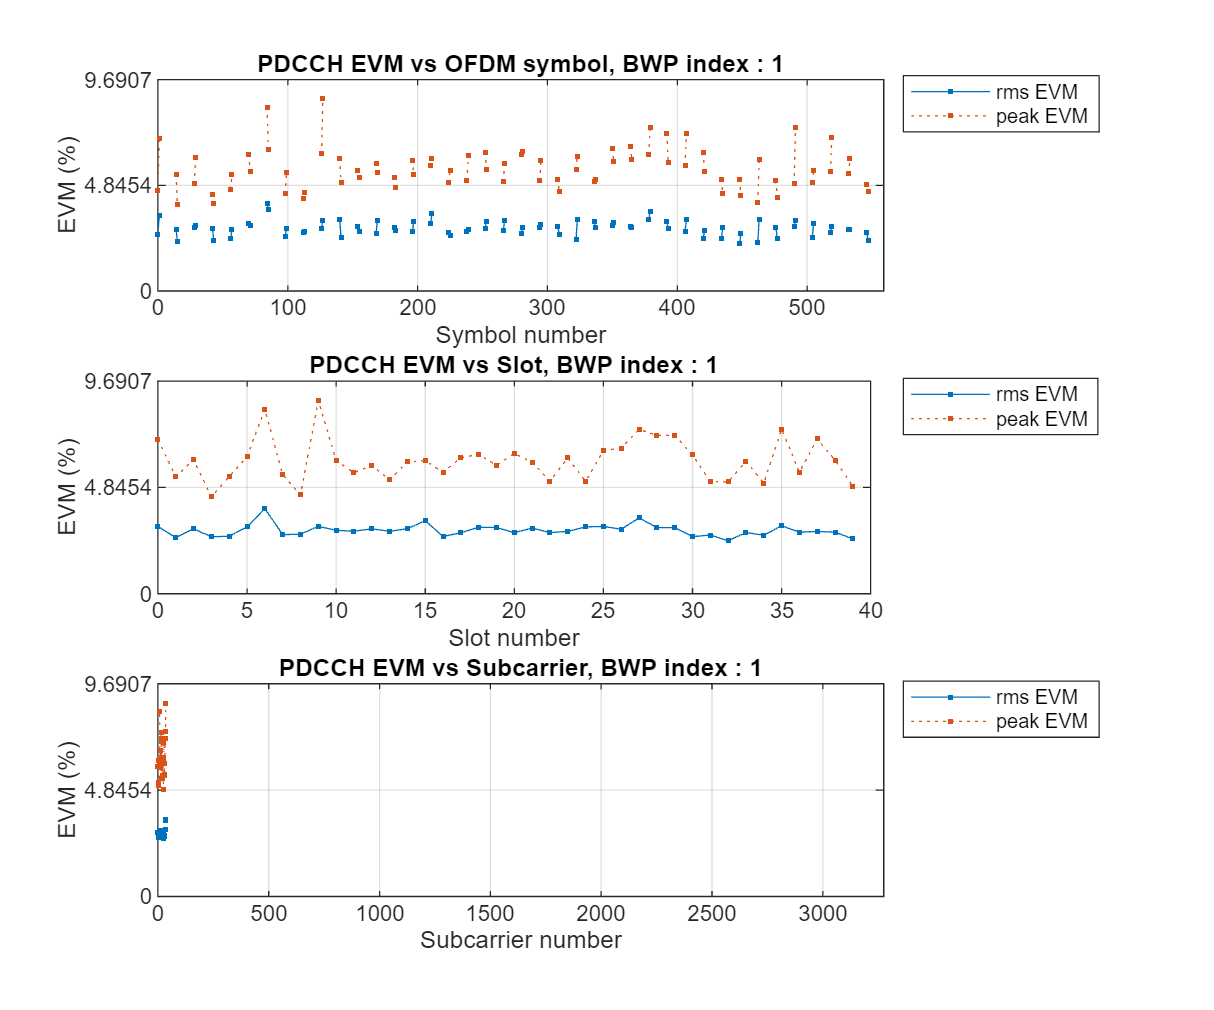

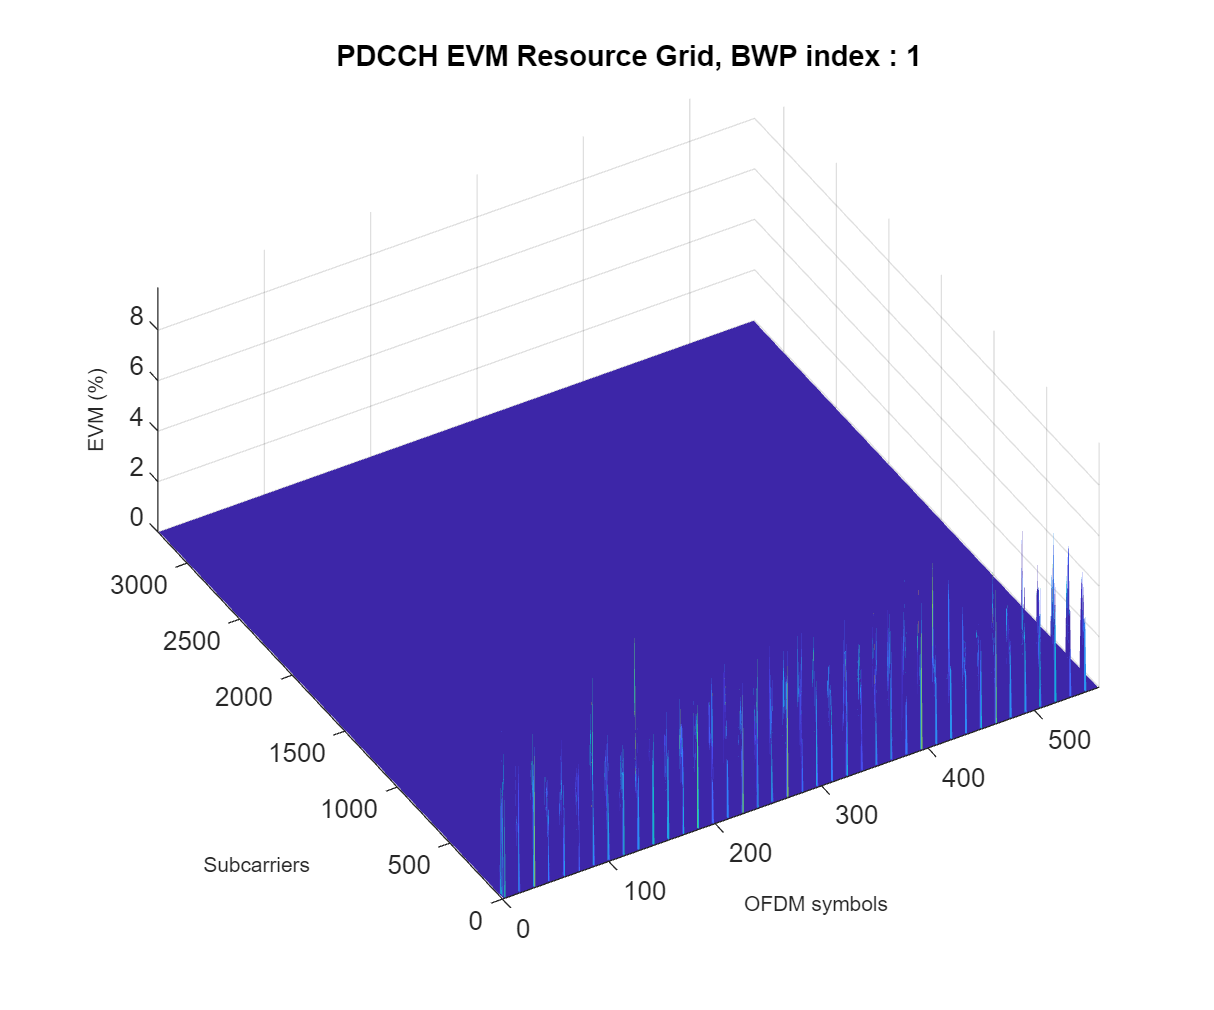

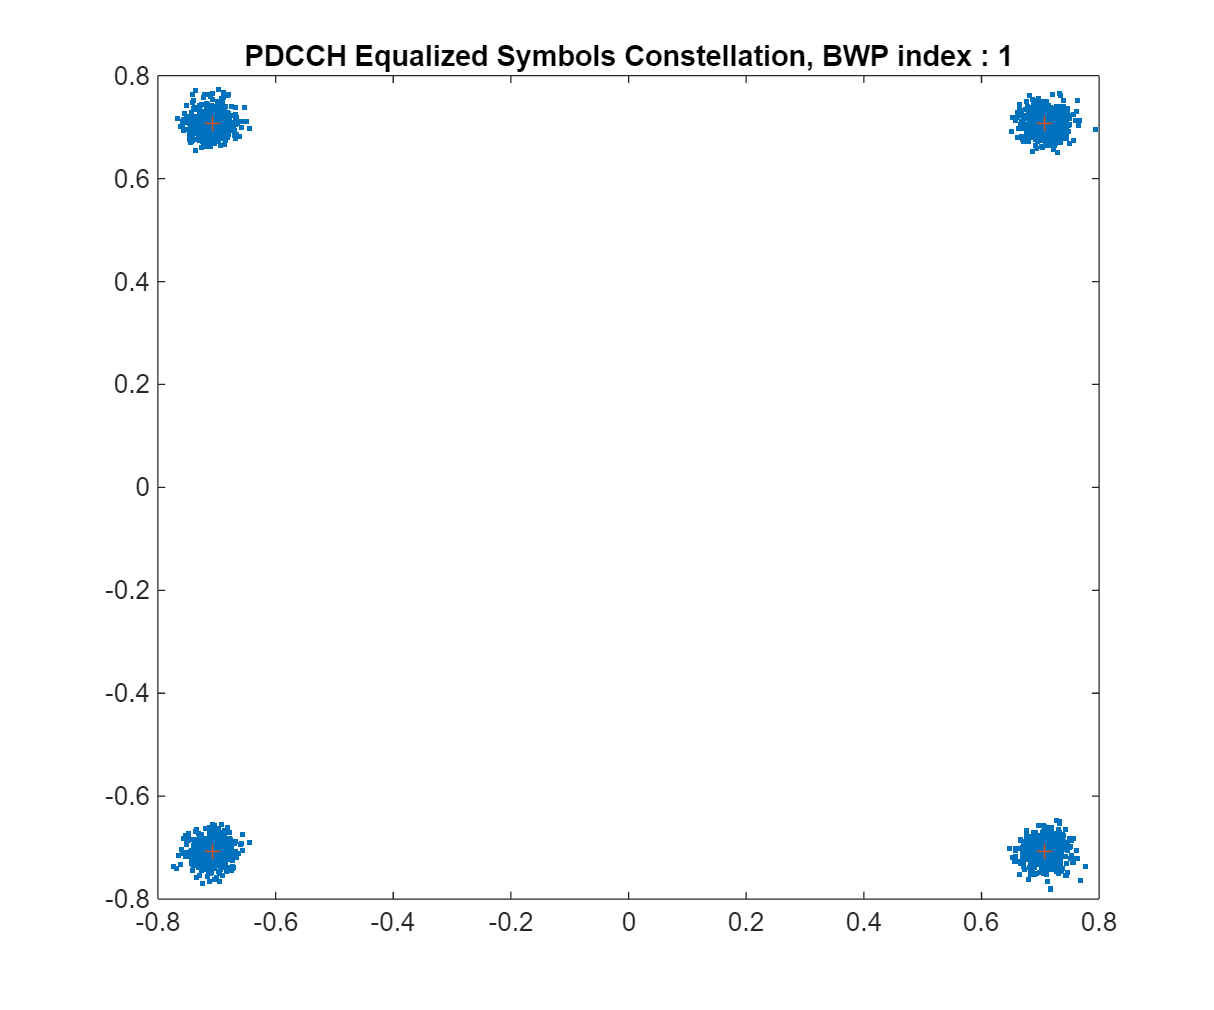

% Now compute and display EVM measurements for the impaired waveform
IQImbalanceON=true;
cfg.PlotEVM = true;
cfg.DisplayEVM = false;
cfg.IQImbalance = IQImbalanceON;
%%%%%%%%%%%%%%%%%% CODE TO ADD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using the same helper function, compute the EVM measurements for the impaired waveform (variable name: waveform).
[evmInfo,eqSym,refSym] = hNRDownlinkEVM(cfgDLTM,waveform,cfg);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp([' Averaged overall PDSCH RMS EVM impaired: ' num2str(evmInfo.PDSCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDSCH RMS EVM impaired: 2.741 %


disp([' Averaged overall PDCCH RMS EVM impaired: ' num2str(evmInfo.PDCCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDCCH RMS EVM impaired: 2.901 %


Notice the difference between the averaged overall PDSCH RMS EVM and the averaged overall PDCCH RMS EVM for both impaired and unimpaired waveforms.

### Observe both waveforms on the Spectrum Analyzer

We can now see how the two waveforms compare in the spectrum analyzer.

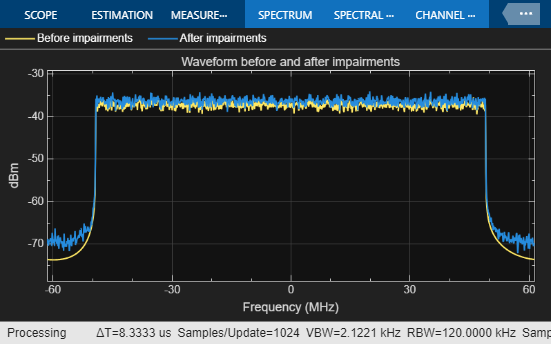

sr = info.ResourceGrids.Info.SampleRate;
scope = spectrumAnalyzer('SampleRate',sr,...
    'ChannelNames',{'Before impairments','After impairments'},...
    'Title', 'Waveform before and after impairments');
%%%%%%%%%%%%%%%%%% CODE TO ADD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Input the two waveforms unimpaired and impaired into the scope function
% Quick help: scope([signal 1,signal 2]);
scope([Unimpaired_waveform,waveform]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


path(p);